close all
clear variables

spectra=importdata("spectra.csv");
starNames=importdata("star_names.csv");
lambdaStart=importdata("lambda_start.csv");
lambdaDelta=importdata("lambda_delta.csv");

lambdaPr=656.28;
speedOfLight=299792.458;

nObs=size(spectra,1);
nStars=size(starNames,1);

lambdaEnd=lambdaStart+(nObs-1)*lambdaDelta;
lambda=(lambdaStart:lambdaDelta:lambdaEnd)';

[starmin,idstarmin]=min(spectra);
lambdaHa=lambda(idstarmin);
z=lambdaHa/lambdaPr-1;
speed=z*speedOfLight

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029



fg1=figure();
set(fg1,"Visible","on");
hold on;
for star=1:nStars
    if speed(star)>0
        plot(lambda,spectra(:,star),'-', ...
            "LineWidth",3);
    else
        plot(lambda,spectra(:,star),'--', ...
            "LineWidth",1);
    end
end

xlabel("Длина волны, нм");
ylabel(["Интенсивность, эрг/см^2/с/"+char(197)]);
title("Спектры звёзд");
legend(starNames);
grid on;
text(lambdaEnd-40, max(max(spectra)), 'Фомин Никита, Б04-006');
movaway=starNames(speed>0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


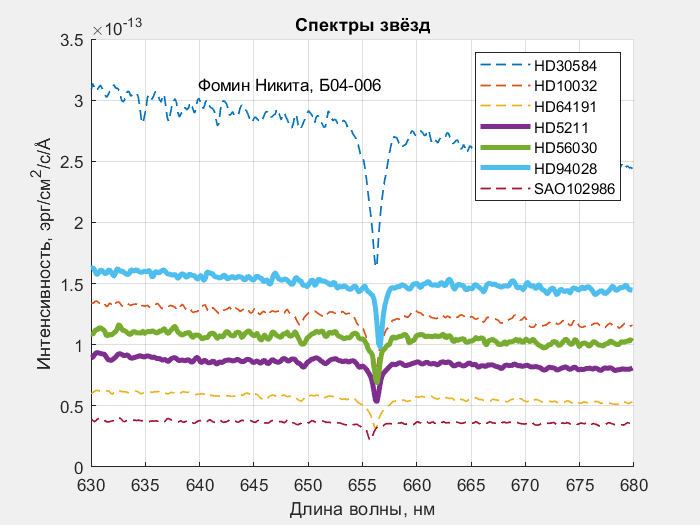

saveas(fg1,"спектры.png")